# 2022 Spring ME112 Introduction to MATLAB Final Exam

12011327 Liu Leqi

## Problem 1

clear all; clc;
R = 1:0.1:1000;
L = 2000./R;
cost = 50*pi*R+40*(2*L+4*R);
fprintf('The minimum cost is %.2f RMB.',min(cost));

The minimum cost is 14245.40 RMB.

idx = find(cost==min(cost));
fprintf('The value of R is %.2f meter, L is %.2f meter',R(idx),2000/R(idx));

The value of R is 22.50 meter, L is 88.89 meter

## Problem 2

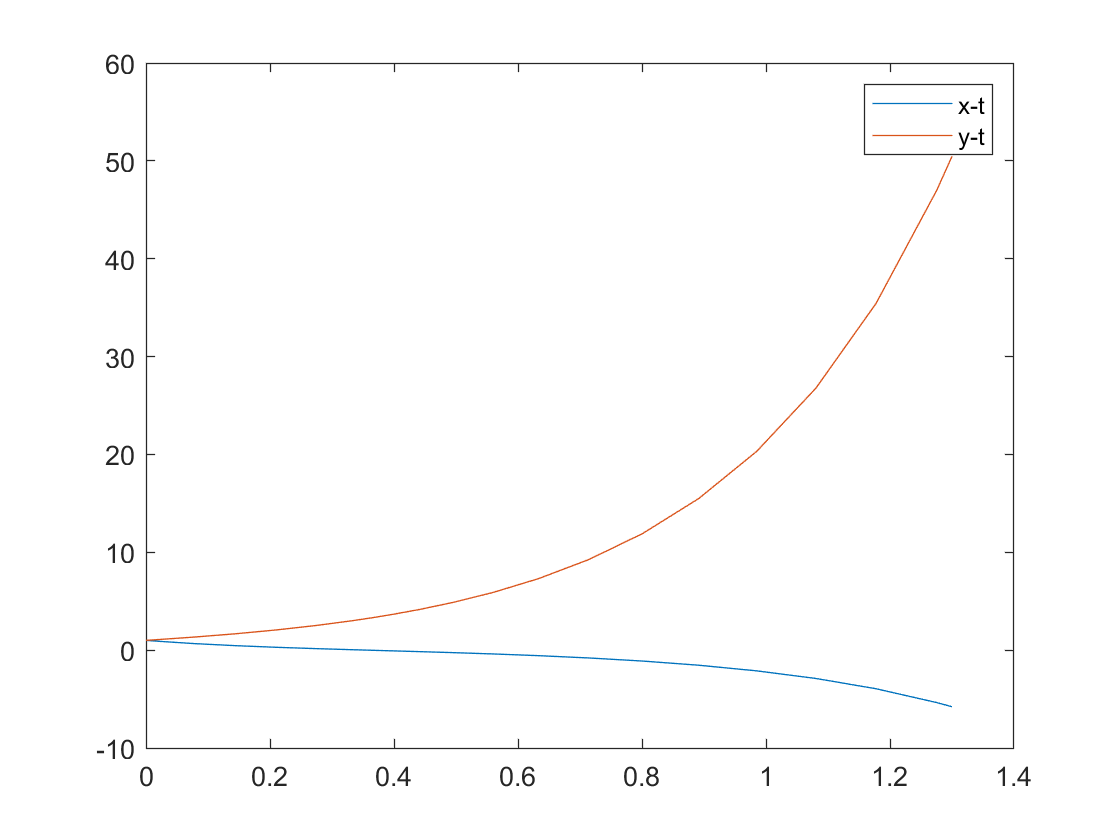

clear all; clc;
% numerical
[tnum,ynum] = ode23(@vdp1, [0 1.3], [1;1]);
plot(tnum,ynum(:,1),tnum,ynum(:,2));
legend('x-t','y-t');
hold off;

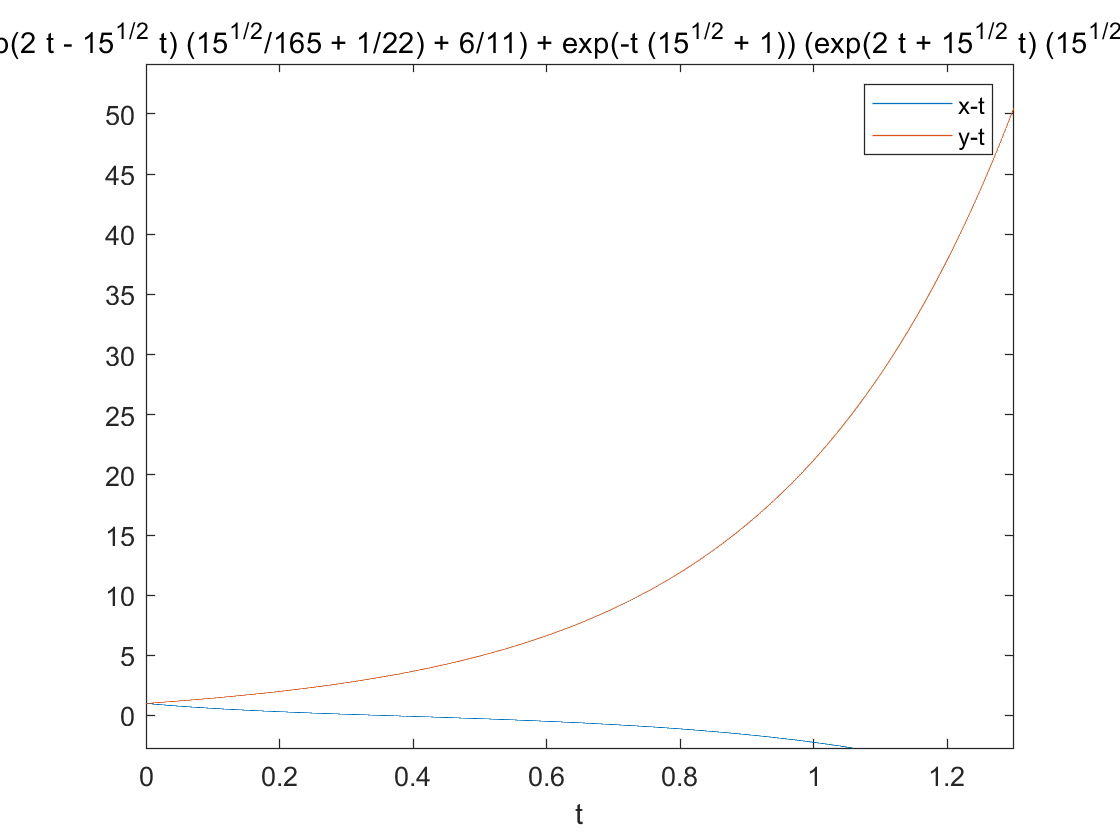

% symbolic
syms x(t) y(t)
equ = [diff(x,t)+5*x+y==exp(t), diff(y,t)-x-3*y==0];
cond = [x(0)==1, y(0)==1];
[xsol(t), ysol(t)] = dsolve(equ,cond);
ezplot(xsol, [0,1.3]);
hold on;
ezplot(ysol, [0,1.3]);
legend('x-t','y-t');
hold off;

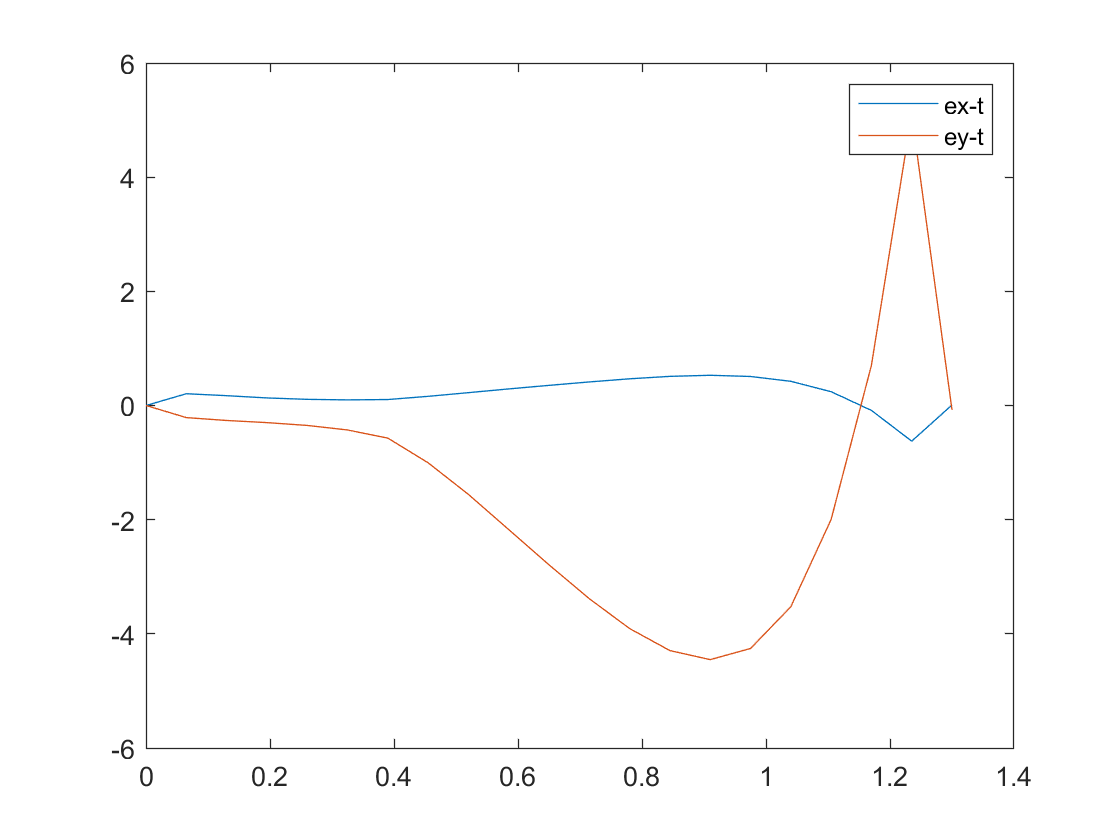

% compare
ex = ynum(:,1)-double(subs(xsol,t,linspace(0,1.3,21)))';
ey = ynum(:,2)-double(subs(ysol,t,linspace(0,1.3,21)))';
tt = linspace(0,1.3,21);
plot(tt,ex,tt,ey);
legend('ex-t','ey-t');

## Problem 3                

clear all; clc;
A = [1 1 -1 -1 0 1;
    0 0 1 1 -1 0;
    0 0 0 0 1 1;
    0 0 0 0 1 -2;
    0 0 1 -2 1 0;
    5 -2 -4 -1 0 1];
resT = zeros(6,1);
resW = 0;
for W = 1:1:600
    B = [W; W; W; 0; 0; 0];
    T = A\B;
    if all(T(T>0))
        if T(1)<=1300 && T(2)<=1300 && T(3)<=500 && T(4)<=500 && T(5)<=300 && T(6)<=300 && resW<W
            resT = T;
            resW = W;
        end
    end
end
fprintf('The maximum W is %.2f N.',resW);

The maximum W is 450.00 N.

## Problem 4

clear all; clc;
% (a)
syms x y b
equc1 = ((x-3)^2+(y-5)^2==4);
equc2 = ((x-5)^2+(y-3)^2==b^2);
res = solve([equc1, equc2], [x y]);
fprintf('The coordinates of the intersection points (x1,y1) and (x2,y2) are: \n');

The coordinates of the intersection points (x1,y1) and (x2,y2) are: 


fprintf('x1='); disp(res.x(1));

x1=

$$\frac{9}{2}-\frac{\sqrt{\frac{\left(-b^{2}+4\,b+4\right)\,\left(b^{2}+4\,b-4\right)}{16}}}{2}-\frac{b^{2}}{8}$$

fprintf('y1='); disp(res.y(1));

y1=

$$\frac{b^{2}}{8}-\frac{\sqrt{\frac{\left(-b^{2}+4\,b+4\right)\,\left(b^{2}+4\,b-4\right)}{16}}}{2}+\frac{7}{2}$$

fprintf('x2='); disp(res.x(2));

x2=

$$\frac{\sqrt{\frac{\left(-b^{2}+4\,b+4\right)\,\left(b^{2}+4\,b-4\right)}{16}}}{2}-\frac{b^{2}}{8}+\frac{9}{2}$$

fprintf('y2='); disp(res.y(2));

y2=

$$\frac{b^{2}}{8}+\frac{\sqrt{\frac{\left(-b^{2}+4\,b+4\right)\,\left(b^{2}+4\,b-4\right)}{16}}}{2}+\frac{7}{2}$$

% (b)
res_b = subs(res,b,sqrt(3));
fprintf('For b=sqrt(3), the coordinates of the intersection points (x1,y1) and (x2,y2) are: \n');

For b=sqrt(3), the coordinates of the intersection points (x1,y1) and (x2,y2) are: 


fprintf('x1='); disp(res_b.x(1));

x1=

$$\frac{33}{8}-\frac{\sqrt{\frac{\left(4\,\sqrt{3}-1\right)\,\left(4\,\sqrt{3}+1\right)}{16}}}{2}$$

fprintf('y1='); disp(res_b.y(1));

y1=

$$\frac{31}{8}-\frac{\sqrt{\frac{\left(4\,\sqrt{3}-1\right)\,\left(4\,\sqrt{3}+1\right)}{16}}}{2}$$

fprintf('x2='); disp(res_b.x(2));

x2=

$$\frac{\sqrt{\frac{\left(4\,\sqrt{3}-1\right)\,\left(4\,\sqrt{3}+1\right)}{16}}}{2}+\frac{33}{8}$$

fprintf('y2='); disp(res_b.y(2));

y2=

$$\frac{\sqrt{\frac{\left(4\,\sqrt{3}-1\right)\,\left(4\,\sqrt{3}+1\right)}{16}}}{2}+\frac{31}{8}$$

## Functions

function yp = vdp1(t,y)
yp = [exp(t)-5*y(1)-y(2); y(1)+3*y(2)];
end